% a)
f = @(x) (x-1)^2*exp(x);
fp = @(x) (x^2-1)*exp(x);
fpp = @(x) (x^2+2*x-1)*exp(x);
[root, iter, xlist] = newton(f, fp, 2, 1e-6)

root =    1.000000589869591


iter =     21


xlist =    2.000000000000000
   1.666666666666667
   1.416666666666667
   1.244252873563218
   1.135418046418532
   1.072002807118831
   1.037252464662030
   1.018966824905443
   1.009572502685051
   1.004809050422313



% b)
for i = xlist
    ek = abs(i-1)
end

ek =    1.000000000000000
   0.666666666666667
   0.416666666666667
   0.244252873563218
   0.135418046418532
   0.072002807118831
   0.037252464662030
   0.018966824905443
   0.009572502685051
   0.004809050422313


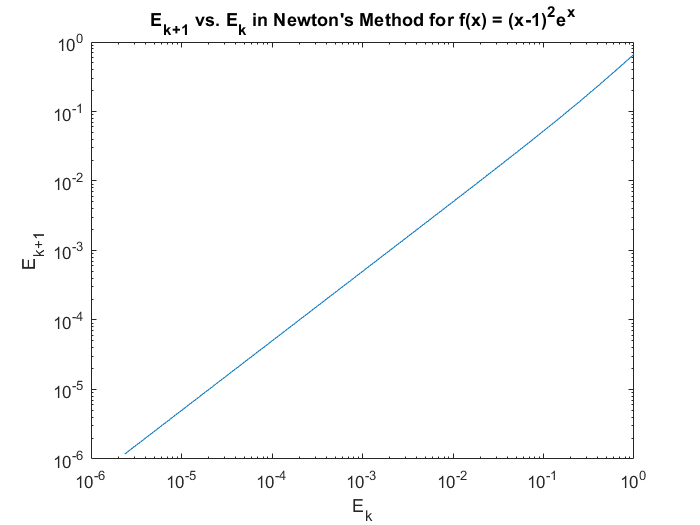

ek1 = circshift(ek,-1);
ek1(22) = 0;
loglog(ek, ek1)
xlabel('E_k')
ylabel('E_k_+_1')
title 'E_k_+_1 vs. E_k in Newton''s Method for f(x) = (x-1)^2e^x'


% c)
[root, iter, xlist] = mnewton(f, fp, fpp, 2, 1e-6);
for i = xlist
    ekk = abs(i-1)
end

ekk =    1.000000000000000
   0.500000000000001
   0.125000000000000
   0.007812500000000
   0.000030517578125
   0.000000000465661


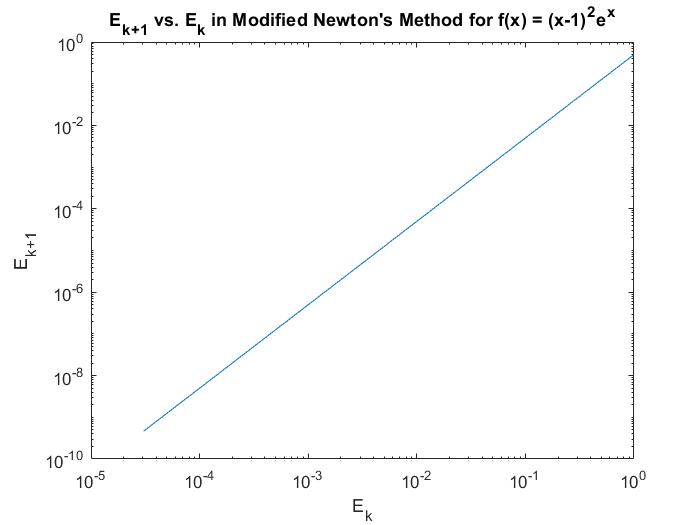

ekk1 = circshift(ekk,-1);
ekk1(6) = 0;
loglog(ekk, ekk1)
xlabel('E_k')
ylabel('E_k_+_1')
title 'E_k_+_1 vs. E_k in Modified Newton''s Method for f(x) = (x-1)^2e^x'

[root, niter, rlist] = bisect2(f, [-15,15], 1e-6)

root =   14.999998211860657


niter =     24


rlist =  -15.000000000000000
  15.000000000000000
                   0
   7.500000000000000
  11.250000000000000
  13.125000000000000
  14.062500000000000
  14.531250000000000
  14.765625000000000
  14.882812500000000
